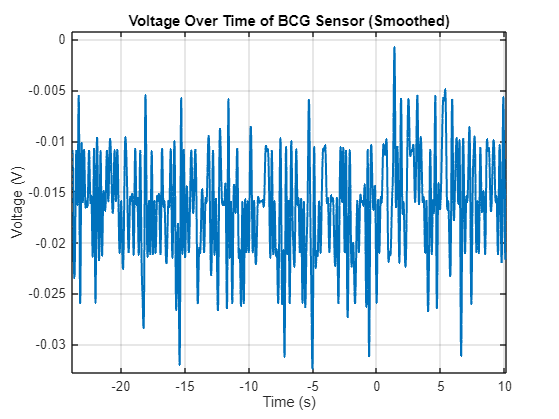

% Read and extract data
heartbeat = table2array(readtable('bcg_lab8.csv'));
time = heartbeat(:,3);
data = heartbeat(:,4);

% Create finer time points
fine_time = linspace(min(time), max(time), 10 * length(time));  % 10x more points

% Use spline interpolation for smoothness
smooth_data = interp1(time, data, fine_time, 'spline');

% Plot the smoothed signal (visually spiky but smooth)
figure()
plot(fine_time, smooth_data, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Voltage Over Time of BCG Sensor (Smoothed)');
grid on

% Axis limits to match your photo
xlim([-23.8 10.11])
ylim([-0.0328 0.00081])